**This code calculate the surface temperature distribution and permitted ice coverage in specified condition. **

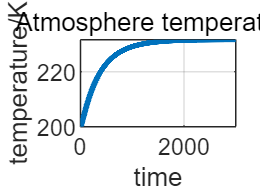

clear;
addpath(genpath('..\function'))

filename='params.xlsx';
data=readmatrix(filename,'Range','A2:I5');

Mr=data(1,1);
Lr=data(1,2);
e=data(1,3);
T_ratio=data(1,4);
gamma=deg2rad(0);
F=1e-3*data(1,6);
precess=0;
a=149598023e3*sqrt(Lr);

G=6.67e-11;     % gravitational constant
L0=3.828e26;     % Sun Luminosity
M0=1.98855e30;      % Sun mass
L=L0*Lr;    % Stellar Luminosity
M=M0*Mr;   % Stellar mass
b=a*sqrt(1-e^2);
T_orb=sqrt(a^3*4*pi^2/(G*M));       % revolution period
T_rot=T_orb/T_ratio;     % rotation period
w=2*pi/T_rot;    % spin velocity
dt=T_rot/200;    % time step
nyear=15;     % integral time
J=2*pi*a*b/T_orb;    % revolution angular momentum


% calculate time sequence of seasonal angle and longitude of substellar point
kappa=0;     % initial seasonal angle
slon=pi;    % initial longitude of substellar point
r=caculate_r(a,e,kappa);
% Euler's forward
[E,~]=Kepler(J,a,e,kappa);
kappa(2)=kappa(1)+dt*E;
slon(2)=slon(1)-dt*(w-E);
while slon(2)<0 || slon(2)>2*pi
    if slon(2)<0
        slon(2)=slon(2)+2*pi;
    else
        slon(2)=slon(2)-2*pi;
    end
end
% Central Difference
while kappa(end)<kappa(1)+2*nyear*pi
    n=size(kappa,2);
    [E,r(n)]=Kepler(J,a,e,kappa(n));
    kappa(n+1)=kappa(n-1)+2*dt*E;
    slon(n+1)=slon(n-1)-2*dt*(w-E);
    while slon(n+1)<0 || slon(n+1)>2*pi
        if slon(n+1)<0
            slon(n+1)=slon(n+1)+2*pi;
        else
            slon(n+1)=slon(n+1)-2*pi;
        end
    end
end
r(n+1)=caculate_r(a,e,kappa(end));

% calculate incident stellar flux of each point
n1=10;     % latitude grid point
n2=20;     % longitude grid point
n3=n+1;     % number of time steps
slat=asin(cos(kappa-precess).*sin(gamma));     %太阳直射纬度
lat=linspace(-pi/2,pi/2,n1);
lon=linspace(0,2*pi,n2);
flux=zeros(n1,n2,n3);        %(lat,lon,time)
for i=1:n1
    for j=1:n2
        for k=1:n3
            flux(i,j,k)=caculate_flux(lat(i),slat(k),lon(j)-slon(k),r(k),L);
        end
    end
end

clearvars -except flux F lat lon ...
dt T_rot L b ps U...
n1 n2 n3 nyear

%set atmos & soil parameters
ps=10000;
U=3;
absorp=1-0.2;      %radiation absorptivity
g=9.8;               %gravitational acceleration
cp=1.04e3;          %specific heat
Cd=0.0015;          %dimensionless drag coefficient
R=8.314/(28e-3);    %gas constant, unit:J/(kg*K) 
ka=ps*cp*Cd*U/R;    %part of heat constant
kc=Cd*U*g*dt/R;
%soil layers 
Kt=2.9;
rcp=2.02e6;            %rock
nz=35;
z=zeros(nz+1,1);
z0=sqrt(Kt*dt/rcp);
for i=1:(nz+1)
    z(i)=z0*(exp((i-1)/5)-1)/(exp(3)-1);
end
dz=zeros(nz,1);
for i=1:nz
    if i<nz
        dz(i)=(z(i+2)-z(i))/2;
    else
        dz(nz)=z(i+1)-z(i);
    end
end

area=caculate_rarea(lat,lon)/(4*pi);
%initial temperature
T=zeros(n1,n2,n3,nz+1);
T0=200;%(sum(mean(flux,3).*area,'all')/absorp)^0.25;
T(:,:,1,:)=T0;     %t=0
Ta=zeros(n3,1);
Ta(:,1)=T0;        %air

m=rcp/dt;
%caculate coef matrix A
A=zeros(nz+1);  
c2=-Kt/(z(2)-z(1));
A(1,2)=c2;
for j=2:nz
    c1=Kt/(dz(j-1)*(z(j)-z(j-1)));
    c3=Kt/(dz(j-1)*(z(j+1)-z(j)));
    c2=-(m+c1+c3);
    A(j,j-1:j+1)=[c1,c2,c3];
end
c1=Kt/(dz(nz)*(z(nz+1)-z(nz)));
c2=-(m+c1);
A(nz+1,nz:nz+1)=[c1,c2];

for i=2:n3
    %surface air temperature
    temp_Tg=sum(T(:,:,i-1,1).*area,'all');
    b=kc-Ta(i-1);
    c=-kc*temp_Tg;
    Ta(i)=(-b+sqrt(b^2-4*c))/2;
    a=ka/Ta(i);
    for nlat=1:n1
        for nlon=1:n2
            %time-related terms in A
            c1=OLR(T(nlat,nlon,i-1,1),1)+Kt/(z(2)-z(1))+a;
            A(1,1)=c1;
            %caculate B
            rad_in=flux(nlat,nlon,i);
            b0=absorp*rad_in+ka ...
                -OLR(T(nlat,nlon,i-1,1),0)+OLR(T(nlat,nlon,i-1,1),1)*T(nlat,nlon,i-1,1);
            temp=squeeze(T(nlat,nlon,i-1,2:nz));
            b_m=cat(1,b0,-m*temp,-m*squeeze(T(nlat,nlon,i-1,nz+1))-F/dz(nz));
            %solve AX=B
            T(nlat,nlon,i,:)= tridiagonal(A,b_m)';
        end
    end
end
T_sur=T(:,:,:,1);

plot(Ta,'LineWidth',2)
title('Atmosphere temperature')
xlabel('time')
ylabel('temperature/K')
grid on

T_sat=170;
flag=0;
while 1
    [t_ice,S_ice,~,ngrid]=calculate_iceage(T_sur,Ta,T_sat,ps,g,lat,lon,n1,n2,n3,nyear);
    if flag==0
        if t_ice>10
            flag=1;
        end
    else
        if t_ice<10 || T_sat>240
            break;
        end
    end
    T_sat=T_sat+1;
end
rarea=S_ice/(4*pi);

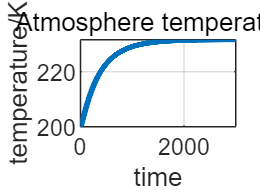

m_proj('robinson','lat',[-90 90],'lon',[-180 180]);
temp=T_sur(:,:,end);
colormap([m_colmap('diverging')]);  

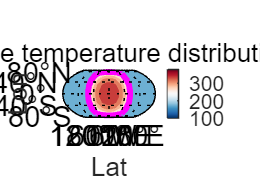

[~,h]=m_contourf(rad2deg(lon)-180,rad2deg(lat),temp,7);
set(h,'Color','none');
clim([100 380]);
c=colorbar;
hold on;
v=[T_sat T_sat];
m_contour(rad2deg(lon)-180,rad2deg(lat),temp,v,'LineWidth',2,'Linecolor','m');
m_grid;
xlabel('Lat')
ylabel('Lon')
title('Surface temperature distribution')
hold off;

% 
% figure
%  plot(rad2deg(lon),squeeze(T_sur(11,:,end),'Linewidth',2));grid on;yline(T_sat,'Linewidth',2);